# NRG: Iterative diagonalization and energy flow

Author: [Seung-Sup Lee](https://cqm.snu.ac.kr)

The numerical renormalization group (NRG) is a tensor network method specialized in solving quantum impurity systems. [Kenneth G. Wilson](https://en.wikipedia.org/wiki/Kenneth_G._Wilson) has itnvented NRG to solve the Kondo problem which was not solvable then. The invention of NRG, indeed, is a part of his Nobel prize citation. NRG is an ancestor of all numerical methods having "renormalization group" in their names.

## Exercise (a): Complete the functions for the logarithmic discretization and the iterative diagonalization

There are two functions, (i) `doCLD_Ex.m` for the Campo–Oliveira logarithmic discretization proposed by Campo2005 [[V. L. Campo and L. N. Oliveira, Phys. Rev. B **72**, 104432 (2005)](https://journals.aps.org/prb/abstract/10.1103/PhysRevB.72.104432)] and (ii) `NRG_IterDiag_Ex.m` for the NRG-style iterative diagonalization, contained in the same sub-directory whith this script. These functions are incomplete. Complete the parts enclosed by the comments `TODO (start)` and `TODO (end)`.

Also answer the "Quick Exercises" appear in the demonstration below.

Note that in this tutorial we use a slightly different convention for indexing the Wilson chain parameters (hopping amplitudes, on-site energies), chain sites, and iteration indices, compared with the convention used in the lecture note. Here, iteration 0 involves only the spaces spanned by the input isometry `A0`; iteration 1 also involves the next site from the bath; and so on. That is, iteration indices in this convention are larger than those in the lecture note's convention by 1.

Once you solve Exercise (a), you can run the following demonstration in which a single-impurity Anderson model (SIAM) is solved by using the NRG. In this example, we consider a box-shaped hybridization function $\Delta'' (\omega) = (\Delta_0 / \pi) \theta (D - \omega)$, where $\omega$ is the half-bandwidth of the bath.

clear

Delta0 = 2.5e-4; % hybridization strength
D = 1; % half-bandwidh
ozin = [-1;1]*D; % frequency grid to define the hybridization
RhoV2in = [1;1]*(Delta0/pi); % hybridization function on the ozin grid

Let's first see whether the logarithmic discretization works correctly.

% NRG parameters
Lambda = 2.5; % discretization parameter
N = 55; % length of the Wilson chain

[ff,gg] = doCLD_Ex (ozin,RhoV2in,Lambda,N);

There are two points to verify your implementation of `doCLD_Ex.m`.

(i) The first element `ff(1)` (= $t_0$ in the lecture note's convention) should be fixed,


$$t_0^2 = \int_{-D}^{D} \mathrm{d}\omega \, \Delta'' (\omega) = 2 \Delta_0 D / \pi,$$


being independent from the choices of `Lambda` (= $\Lambda$). [**Quick Exercise 1:** why?]

(ii) The elements `ff(n)` should scale as $\Lambda^{-n/2}$ for sufficiently large $n$. [**Quick Exercise 2**: Why $\Lambda^{-n/2}$, not $\Lambda^{-n}$? We started from the discretization grid of $\pm \Lambda^{-n}$, so it might look weird to have factor 1/2 in the exponent; but of course, there is a good reason.]

We first check the first point.

disp(ff(1)^2 - 2*Delta0*D/pi)

  -2.7105e-20



And we check the second point by mulitping rescaling factor $\Lambda^{n/2}$.

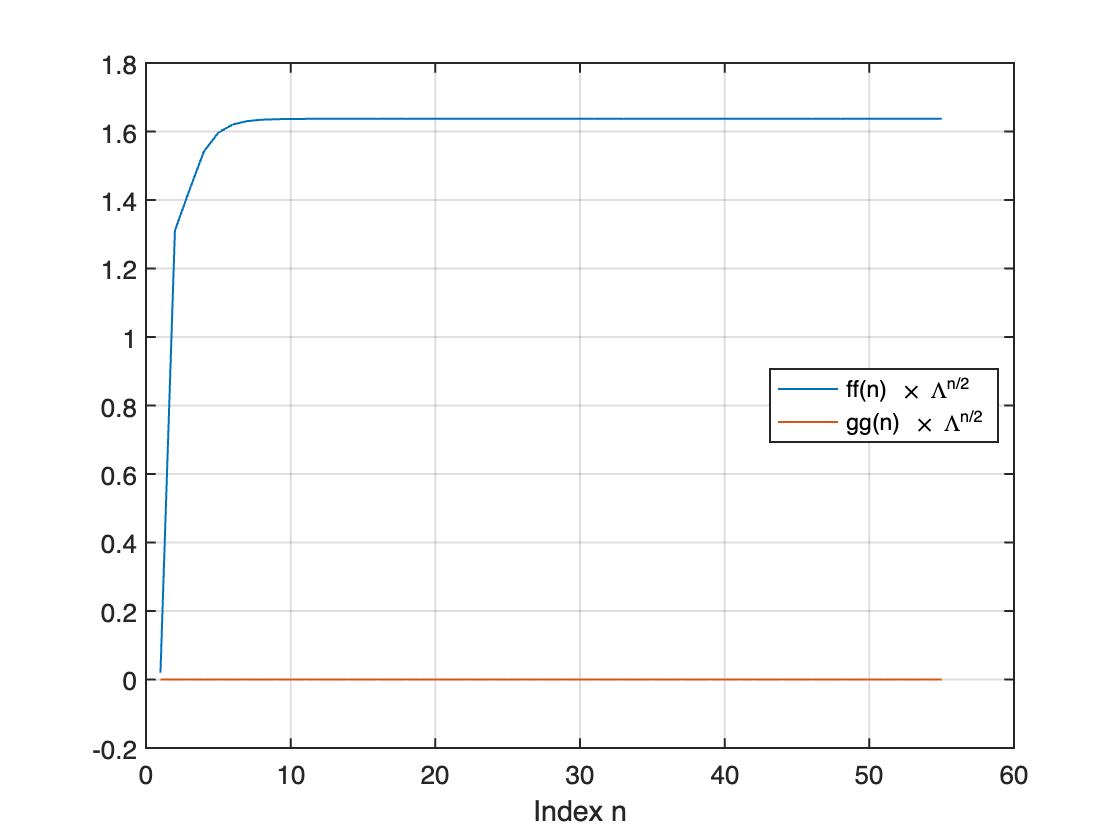

figure;
plot([ff gg].*(Lambda.^((1:numel(ff)).'/2)), ...
    'LineWidth',1);
set(gca,'FontSize',13,'LineWidth',1);
grid on;
xlabel('Index n');
legend({'ff(n) \times \Lambda^{n/2}', ...
    'gg(n) \times \Lambda^{n/2}'}, ...
    'Location','east');

The first elements of `ff` deviate from the exponential dependence, as we see the deviation from the horizontal line. They come from the specific details of the hybridization function, such as a sharp edge at $\omega = \pm D$ for the box-shaped hybridization function.

Set the parameters that define the Anderson impurity.

% Impurity Hamiltonian parameters
U = 4e-3; % Coulomb interaction at the impurity
epsd = -U/2; % impurity on-site energy

% Construct local operators
[F,Z,S,I] = getLocalSpace('FermionS');

% Particle number operators
NF = cat(3,contract(conj(F(:,:,1)),3,[1 3],F(:,:,1),3,[1 3]), ...
           contract(conj(F(:,:,2)),3,[1 3],F(:,:,2),3,[1 3]));
       
% Impurity Hamiltonian
H0 = U*(NF(:,:,1)*NF(:,:,2)) + epsd*(NF(:,:,1)+NF(:,:,2));

% ket tensor for the impurity
A0 = getIdentity(1,2,I,2,[1 3 2]); % 1 for dummy leg

Let's run the iterative diagonalization.

% NRG parameter
Nkeep = 300;

% iterative diagonalization
Inrg = NRG_IterDiag_Ex (H0,A0,Lambda,ff,F,gg,sum(NF,3),Z,Nkeep);

22-10-18 11:04:12 | NRG: start
22-10-18 11:04:12 | #00/55 : NK=4/4, EK=0/0
22-10-18 11:04:12 | #01/55 : NK=16/16, EK=0.04878/0.04878
22-10-18 11:04:12 | #02/55 : NK=64/64, EK=3.207/3.207
22-10-18 11:04:12 | #03/55 : NK=256/256, EK=6.221/6.221
22-10-18 11:04:13 | #04/55 : NK=328/1024, EK=4.999/13.01
22-10-18 11:04:13 | #05/55 : NK=304/1312, EK=4.681/9.125
22-10-18 11:04:13 | #06/55 : NK=328/1216, EK=5.009/10.56
22-10-18 11:04:13 | #07/55 : NK=304/1312, EK=4.741/9.182
22-10-18 11:04:14 | #08/55 : NK=328/1216, EK=5.038/10.6
22-10-18 11:04:14 | #09/55 : NK=304/1312, EK=4.852/9.268
22-10-18 11:04:14 | #10/55 : NK=328/1216, EK=5.109/10.7
22-10-18 11:04:14 | #11/55 : NK=304/1312, EK=5.048/9.432
22-10-18 11:04:15 | #12/55 : NK=328/1216, EK=5.265/10.92
22-10-18 11:04:15 | #13/55 : NK=300/1312, EK=5.305/9.782
22-10-18 11:04:15 | #14/55 : NK=328/1200, EK=5.554/11.22
22-10-18 11:04:15 | #15/55 : NK=320/1312, EK=5.712/10.54
22-10-18 11:04:15 | #16/55 : NK=306/1280, EK=5.863/11.25
22-10-18 11:04:16 

Each message line from the `NRG_IterDiag` indicates time stamp, number of the kept states, number of the total states, the largest energy of the kept states, the largest energy of the discarded states.

## Energy flow diagam

NRG provides a method to analyze the spectrum obtained along the iterative diagonalization. Let's plot the lowest-lying (many-body) energy levels. We plot the results from even iterations and those from odd iterations separately.

% Energy flow diagram
Eshow = 3; % energy window to show (from 0 to Eshow)

% since we start from A0; consider the step for H0 as 0, i.e., even
Eeven = Inrg.EK(1:2:end);
Eeven = cellfun(@(x) x(x <= Eshow), Eeven, 'UniformOutput', 0);
maxEeven = max(cellfun('prodofsize',Eeven));
Eeven = cellfun(@(x) [x;nan(maxEeven-numel(x),1)], Eeven, 'UniformOutput', 0);
Eeven = cell2mat(Eeven).';

Eodd = Inrg.EK(2:2:end);
Eodd = cellfun(@(x) x(x <= Eshow), Eodd, 'UniformOutput', 0);
maxEodd = max(cellfun('prodofsize',Eodd));
Eodd = cellfun(@(x) [x;nan(maxEodd-numel(x),1)], Eodd, 'UniformOutput', 0);
Eodd = cell2mat(Eodd).';

(Note that `cellfun('prodofsize', ...)` is undocumented functionality, which gives the same result as `cellfun(@numel, ...)` but much faster. Refer to [this webpage](http://undocumentedmatlab.com/blog/cellfun-undocumented-performance-boost).)

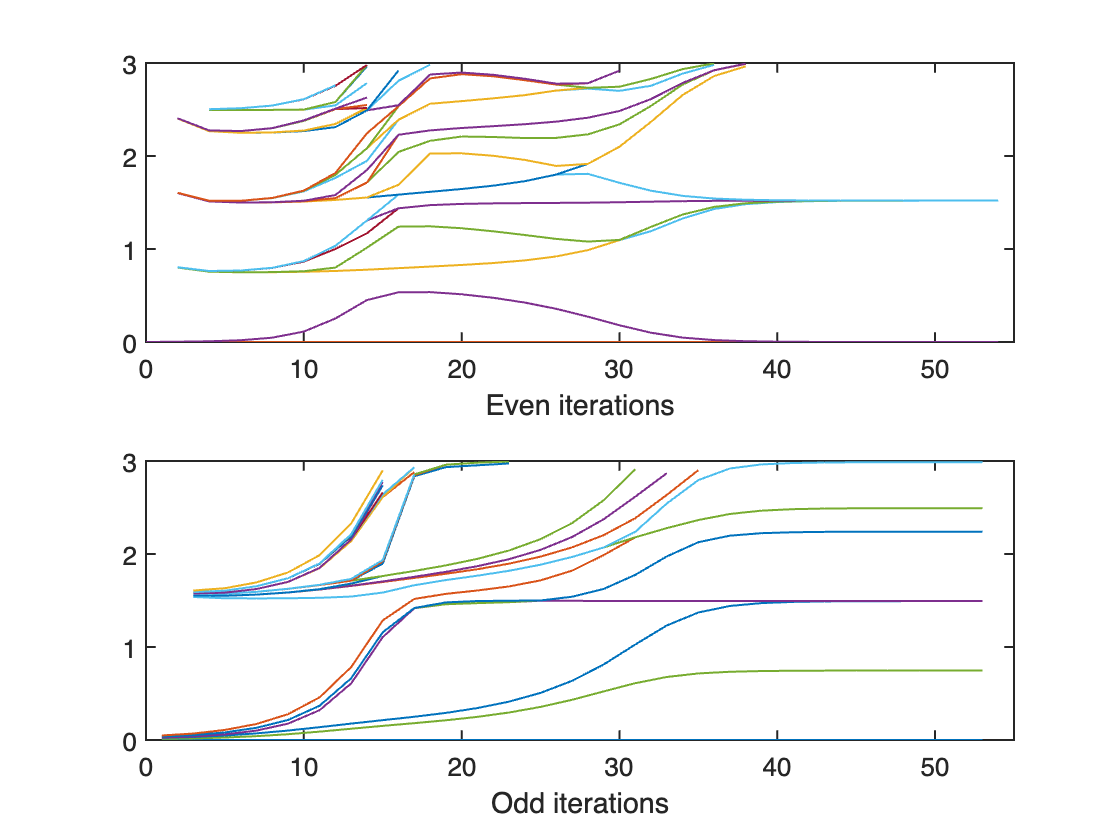

figure;
% upper panel
subplot(2,1,1);
plot((1:2:numel(Inrg.EK))-1,Eeven,'LineWidth',1);
xlabel('Even iterations');
xlim([0 numel(Inrg.EK)-1]);
ylim([0, Eshow]);
set(gca,'LineWidth',1,'FontSize',13);

% lower panel
subplot(2,1,2);
plot((2:2:numel(Inrg.EK))-1,Eodd,'LineWidth',1);
xlabel('Odd iterations');
xlim([0 numel(Inrg.EK)-1]);
ylim([0, Eshow]);
set(gca,'LineWidth',1,'FontSize',13);

(Note that `cellfun('prodofsize', ...)` is undocumented functionality, which gives the same result as `cellfun(@numel, ...)` but much faster. Refer to [this webpage](http://undocumentedmatlab.com/blog/cellfun-undocumented-performance-boost).)

These plots are called energy flow diagrams or finite-size energy spectra. The name "flow" literally comes from that the lines flow from one regime to the other. There are three regions (iterations 1–10; 17–25; 35–55) connected via two crossovers. These regions correspond to different fixed points: free orbital, local moment, and strong coupling. The strong-coupling fixed-point regime exhibits prominent plateau of the energy levels.

## Exercise (b): Reproduce lowest-lying energies in the strong-coupling regime by fixed-point Hamiltonians

Let's consider iteration 53 (counting from iteration 0 for the impurity only) in the strong-coupling fixed-point regime. Their lowet-lying energies, including all degenerate levels, are:

fprintf([sprintf('%.4f, ',Inrg.EK{54}(1:5).'),'\n', ...
    sprintf('%.4f, ',Inrg.EK{54}(6:11).'),'...\n']);

0.0000, 0.7468, 0.7468, 0.7468, 0.7468, 
1.4937, 1.4937, 1.4937, 1.4937, 1.4937, 1.4937, ...


We see 1-fold, 4-fold, and 6-fold degeneracies. On the other hand, the energy levels at the next iteration 54 have more degeneracies:

fprintf([sprintf('%.4f, ',Inrg.EK{55}(1:4).'),'\n', ...
    sprintf('%.4f, ',Inrg.EK{55}(5:12).'),'\n', ...
    sprintf('%.4f, ',Inrg.EK{55}(13:20).'),'...\n']);

0.0000, 0.0000, 0.0000, 0.0000, 
1.5205, 1.5205, 1.5205, 1.5205, 1.5205, 1.5205, 1.5205, 1.5205, 
1.5205, 1.5205, 1.5205, 1.5205, 1.5205, 1.5205, 1.5205, 1.5205, ...


There are 4-fold and 16-fold degeneracies, up to numerical noise of $O(10^{-6})$.

Reproduce these (many-body) energy values by considering strong-coupling fixed-point Hamiltonians.

(*Hint*: The fixed-point Hamiltonians are single-particle Hamiltonians, effectively!)

## Exercise (c): Single-impurity Kondo model

We can derive the Wilson chain Hamiltonian for the single-impurity Kondo model (SIKM), from the chain Hamiltonian of the SIAM. By applying the [Schrieffer–Wolff transformation](https://en.wikipedia.org/wiki/Schrieffer%E2%80%93Wolff_transformation) (SWT) to the impurity site (on which $\hat{d}_\sigma$ acts) and the first bath site (on which $\hat{f}_{0\sigma}$ acts), we obtain


$$\hat{H}_\mathrm{SIKM} = 2J \hat{\vec{S}}_d \cdot \hat{\vec{S}}_0 + \sum_{n = 1}^{N} \sum_{\sigma=\uparrow,\downarrow} (t_n \hat{f}_{n\sigma}^\dagger f_{n-1,\sigma} + \mathrm{h.c.}) + \sum_{n=0}^{N} \sum_{\sigma=\uparrow,\downarrow} \epsilon_n \hat{f}_{n\sigma}^\dagger \hat{f}_{n\sigma}.$$


Here $\hat{\vec{S}}_d$ is the spin operator acting on the impurity site,


$$\hat{\vec{S}}_0 = \sum_{\sigma,\sigma'} \hat{f}_{0\sigma}^\dagger \frac{\vec{\sigma}_{\sigma,\sigma'}}{2} \hat{f}_{0\sigma'}$$


is the spin operator acting on the first bath site, $\vec{\sigma} = [\sigma_x, \sigma_y, \sigma_z]$ is the vector of the Pauli matrices, and


$$J = t_0^2 \left( \frac{1}{-\epsilon_d} + \frac{1}{U + \epsilon_d} \right)$$


is the Kondo coupling strength. For particle-hole symmetric case $\epsilon_d = -U/2$ which we considered above, it becomes


$$J = \frac{4 t_0^2}{U} = \frac{8 \Delta_0 D}{\pi U}.$$


The remaining bath term is the same as in the SIAM case. Note that the impurity site in the SIKM has dimension 2, while that in the SIAM has 4; the doubly occupied and the empty states are "integrated out" by the SWT. Refer to Schrieffer1966 [[J. R. Schrieffer and P. A. Wolff, Phys. Rev. **149**, 491 (1966)](https://journals.aps.org/pr/abstract/10.1103/PhysRev.149.491)]) for the details of the SWT.

Perform the iterative diagonalization of this chain Hamiltonian for the SIKM, with the value of $J$ corresponding to the choice of parameters $U$, $\epsilon_d$, $\Gamma$, and $D$ used for the SIAM above. Compare the energy flow diagram with the SIAM result.